%clear
%clc

%load('base_path.mat')
%for x =[216 288 432 864 2160]
specifier = '864\'

specifier = '2160\'

folder = 'QueryPoints\'

folder = 'QueryPoints\'

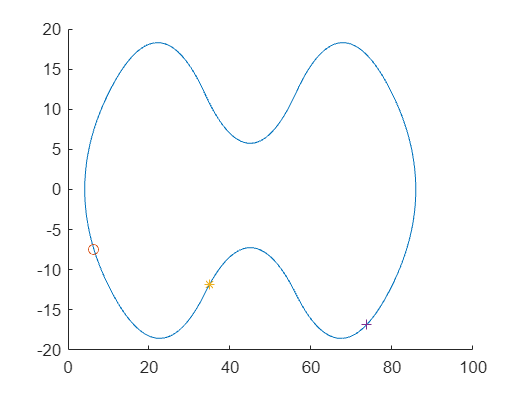

x_wp = path.VarName1;
y_wp = path.VarName2;

%{
QP_x = [];
QP_y = [];

%QP_x = x_wp;
%QP_y = y_wp;



for i =1:length(x_wp)-1
    A = [x_wp(i),y_wp(i)];
    B = [x_wp(i+1),y_wp(i+1)];
    N= 5;
    x = [A(1) B(1)];
    y = [A(2) B(2)];
    qp_x = linspace(x(1),x(2),N+2);
    qp_y = linspace(y(1),y(2),N+2);
    qp_x(end)=[];
    qp_x(1)=[];
    QP_x = [QP_x,qp_x];
    qp_y(end)=[];
    qp_y(1)=[];
    QP_y = [QP_y,qp_y];
end

%}

base_path = [x_wp y_wp]';

figure
hold on
plot(base_path(1,:),base_path(2,:))
plot(base_path(1,10),base_path(2,10),'o')
plot(base_path(1,50),base_path(2,50),'*')
plot(base_path(1,100),base_path(2,100),'+')
hold off

set = [base_path(1,:)' base_path(2,:)'];
set1 = circshift(set,-1*50);
set1_ = flip(set1);
set2 =  circshift(set1,-1*100);
set2_ = flip(set2);
set3 =  circshift(set1,-2*100);
set3_ = flip(set3);
set4 =  circshift(set1,-3*100);
set4_ = flip(set4);
set5 =  circshift(set1,-4*100);
set5_ = flip(set5);


A = 2;
B=3;
C=5;


figure
hold on
set1 = set1'

set1 =    35.6156   36.2902   36.9852   37.7017   38.4405   39.2019   39.9857   40.7910   41.6164   42.4593   43.3165   44.1840   45.0564   45.9285   46.7949   47.6505   48.4913   49.3143   50.1170   50.8979   51.6564   52.3923   53.1059   53.7982   54.4700   55.1226   55.7560   56.3739   56.9970   57.6405   58.3043   58.9890   59.6956   60.4249   61.1772   61.9526   62.7501   63.5684   64.4052   65.2573   66.1209   66.9916   67.8646   68.7349   69.5980   70.4498   71.2869   72.1073   72.9094   73.6921
  -11.2526  -10.6981  -10.1696   -9.6707   -9.2053   -8.7779   -8.3932   -8.0562   -7.7718   -7.5446   -7.3790   -7.2815   -7.2518   -7.2900   -7.3972   -7.5707   -7.8053   -8.0967   -8.4401   -8.8305   -9.2631   -9.7331  -10.2362  -10.7683  -11.3260  -11.9061  -12.5072  -13.1242  -13.7359  -14.3261  -14.8934  -15.4352  -15.9481  -16.4282  -16.8713  -17.2729  -17.6281  -17.9324  -18.1814  -18.3711  -18.4984  -18.5613  -18.5576  -18.4881  -18.3570  -18.1656  -17.9178  -17.6193  -17.2744  

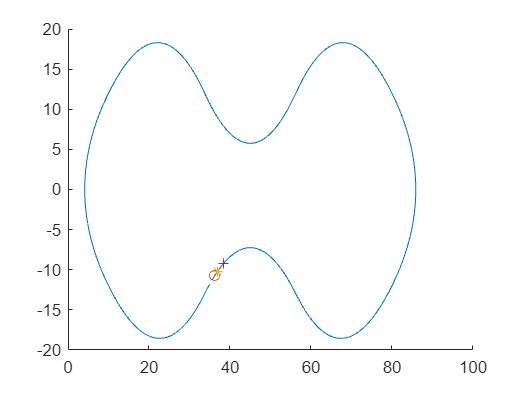

plot(set1(1,:),set1(2,:))
plot(set1(1,A),set1(2,A),'o')
plot(set1(1,B),set1(2,B),'*')
plot(set1(1,C),set1(2,C),'+')
hold off


figure
hold on
set1_ = set1_'

set1_ =    34.9605   34.3248   33.7057   33.0847   32.4437   31.7826   31.1008   30.3972   29.6708   28.9211   28.1488   27.3542   26.5385   25.7039   24.8536   23.9912   23.1211   22.2481   21.3773   20.5131   19.6594   18.8204   17.9977   17.1932   16.4081   15.6427   14.8972   14.1713   13.4643   12.7756   12.1041   11.4496   10.8115   10.1879    9.5802    8.9903    8.4191    7.8691    7.3442    6.8459    6.3773    5.9419    5.5435    5.1861    4.8737    4.6103    4.4019    4.2501    4.1573    4.1250
  -11.8298  -12.4285  -13.0442  -13.6581  -14.2510  -14.8214  -15.3668  -15.8838  -16.3684  -16.8160  -17.2232  -17.5852  -17.8964  -18.1527  -18.3501  -18.4854  -18.5566  -18.5623  -18.5007  -18.3772  -18.1941  -17.9529  -17.6605  -17.3213  -16.9395  -16.5193  -16.0648  -15.5796  -15.0671  -14.5304  -13.9723  -13.3942  -12.7981  -12.1869  -11.5599  -10.9161  -10.2557   -9.5775   -8.8797   -8.1627   -7.4260   -6.6692   -5.8923   -5.0957   -4.2804   -3.4480   -2.6002   -1.7405   -0.8724 

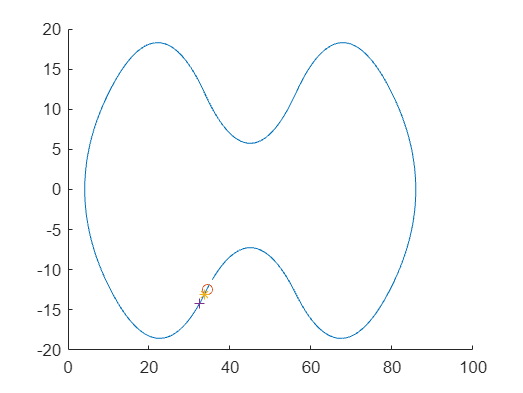

plot(set1_(1,:),set1_(2,:))
plot(set1_(1,A),set1_(2,A),'o')
plot(set1_(1,B),set1_(2,B),'*')
plot(set1_(1,C),set1_(2,C),'+')
hold off




figure
hold on
set2 = set2'

set2 =    72.6630   71.8480   71.0150   70.1660   69.3046   68.4352   67.5623   66.6913   65.8273   64.9754   64.1399   63.3236   62.5288   61.7571   61.0090   60.2848   59.5841   58.9059   58.2492   57.6128   56.9969   56.3996   55.8091   55.2028   54.5780   53.9337   53.2686   52.5812   51.8703   51.1358   50.3767   49.5931   48.7862   47.9581   47.1115   46.2501   45.3801   44.5072   43.6380   42.7782   41.9338   41.1082   40.3042   39.5238   38.7681   38.0366   37.3288   36.6440   35.9818   35.3402
   17.2999   17.6129   17.8746   18.0777   18.2198   18.2984   18.3076   18.2492   18.1245   17.9334   17.6804   17.3710   17.0097   16.6015   16.1512   15.6634   15.1426   14.5927   14.0172   13.4193   12.8004   12.1635   11.5201   10.8918   10.2819    9.6925    9.1268    8.5884    8.0813    7.6094    7.1780    6.7929    6.4595    6.1834    5.9706    5.8288    5.7579    5.7633    5.8431    5.9940    6.2158    6.4994    6.8397    7.2311    7.6685    8.1452    8.6565    9.1982    9.7673  

set2_ = set2_'

set2_ =    73.4585   74.2336   74.9881   75.7220   76.4359   77.1306   77.8070   78.4653   79.1065   79.7324   80.3421   80.9345   81.5084   82.0611   82.5892   83.0912   83.5639   84.0038   84.4072   84.7700   85.0884   85.3582   85.5745   85.7336   85.8340   85.8739   85.8506   85.7652   85.6207   85.4194   85.1634   84.8570   84.5052   84.1118   83.6810   83.2165   82.7219   82.2002   81.6531   81.0847   80.4971   79.8915   79.2699   78.6338   77.9814   77.3121   76.6257   75.9212   75.1978   74.4549
   16.9402   16.5384   16.0989   15.6259   15.1232   14.5942   14.0421   13.4684   12.8757   12.2668   11.6418   11.0003   10.3421    9.6661    8.9708    8.2564    7.5223    6.7681    5.9938    5.1997    4.3867    3.5564    2.7105    1.8521    0.9849    0.1128   -0.7599   -1.6287   -2.4896   -3.3392   -4.1739   -4.9914   -5.7905   -6.5699   -7.3294   -8.0687   -8.7882   -9.4884  -10.1690  -10.8318  -11.4777  -12.1068  -12.7200  -13.3182  -13.8985  -14.4594  -14.9991  -15.5149  -16.0039 

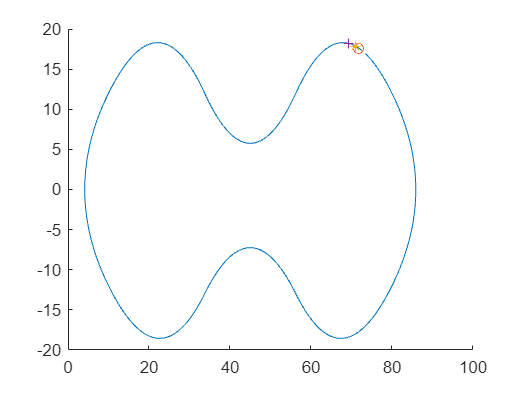

plot(set2(1,:),set2(2,:))
plot(set2(1,A),set2(2,A),'o')
plot(set2(1,B),set2(2,B),'*')
plot(set2(1,C),set2(2,C),'+')
hold off


figure
hold on
set3 = set3'

set3 =     4.1250    4.1573    4.2501    4.4019    4.6103    4.8737    5.1861    5.5435    5.9419    6.3773    6.8459    7.3442    7.8691    8.4191    8.9903    9.5802   10.1879   10.8115   11.4496   12.1041   12.7756   13.4643   14.1713   14.8972   15.6427   16.4081   17.1932   17.9977   18.8204   19.6594   20.5131   21.3773   22.2481   23.1211   23.9912   24.8536   25.7039   26.5385   27.3542   28.1488   28.9211   29.6708   30.3972   31.1008   31.7826   32.4437   33.0847   33.7057   34.3248   34.9605
         0   -0.8724   -1.7405   -2.6002   -3.4480   -4.2804   -5.0957   -5.8923   -6.6692   -7.4260   -8.1627   -8.8797   -9.5775  -10.2557  -10.9161  -11.5599  -12.1869  -12.7981  -13.3942  -13.9723  -14.5304  -15.0671  -15.5796  -16.0648  -16.5193  -16.9395  -17.3213  -17.6605  -17.9529  -18.1941  -18.3772  -18.5007  -18.5623  -18.5566  -18.4854  -18.3501  -18.1527  -17.8964  -17.5852  -17.2232  -16.8160  -16.3684  -15.8838  -15.3668  -14.8214  -14.2510  -13.6581  -13.0442  -12.4285  

set3_ = set3_'

set3_ =     4.1250    4.1573    4.2501    4.4019    4.6103    4.8737    5.1861    5.5435    5.9419    6.3773    6.8459    7.3442    7.8691    8.4191    8.9903    9.5802   10.1879   10.8118   11.4508   12.1070   12.7811   13.4733   14.1846   14.9159   15.6677   16.4401   17.2331   18.0457   18.8765   19.7235   20.5835   21.4522   22.3249   23.1964   24.0616   24.9154   25.7532   26.5721   27.3697   28.1444   28.8955   29.6228   30.3266   31.0077   31.6672   32.3062   32.9245   33.5242   34.1138   34.7179
    0.0000    0.8724    1.7405    2.6002    3.4480    4.2804    5.0957    5.8923    6.6692    7.4260    8.1627    8.8797    9.5775   10.2557   10.9161   11.5599   12.1869   12.7978   13.3929   13.9690   14.5241   15.0563   15.5626   16.0397   16.4837   16.8906   17.2560   17.5751   17.8435   18.0551   18.2050   18.2916   18.3105   18.2605   18.1440   17.9621   17.7165   17.4140   17.0590   16.6565   16.2114   15.7283   15.2116   14.6653   14.0930   13.4979   12.8813   12.2467   11.6026 

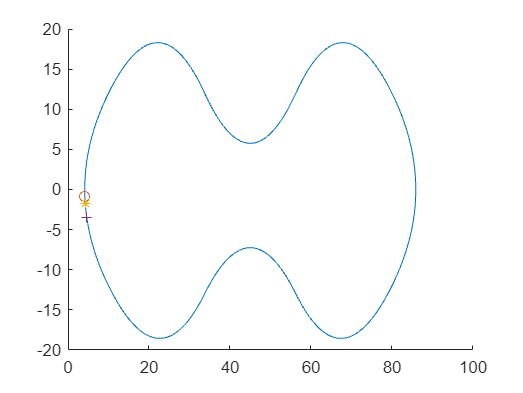

plot(set3(1,:),set3(2,:))
plot(set3(1,A),set3(2,A),'o')
plot(set3(1,B),set3(2,B),'*')
plot(set3(1,C),set3(2,C),'+')
hold off


figure
hold on
set4 = set4'

set4 =    74.4549   75.1978   75.9212   76.6257   77.3121   77.9814   78.6338   79.2699   79.8915   80.4971   81.0847   81.6531   82.2002   82.7219   83.2165   83.6810   84.1118   84.5052   84.8570   85.1634   85.4194   85.6207   85.7652   85.8506   85.8739   85.8340   85.7336   85.5745   85.3582   85.0884   84.7700   84.4072   84.0038   83.5639   83.0912   82.5892   82.0611   81.5084   80.9345   80.3421   79.7324   79.1065   78.4653   77.8070   77.1306   76.4359   75.7220   74.9881   74.2336   73.4585
  -16.4626  -16.0039  -15.5149  -14.9991  -14.4594  -13.8985  -13.3182  -12.7200  -12.1068  -11.4777  -10.8318  -10.1690   -9.4884   -8.7882   -8.0687   -7.3294   -6.5699   -5.7905   -4.9914   -4.1739   -3.3392   -2.4896   -1.6287   -0.7599    0.1128    0.9849    1.8521    2.7105    3.5564    4.3867    5.1997    5.9938    6.7681    7.5223    8.2564    8.9708    9.6661   10.3421   11.0003   11.6418   12.2668   12.8757   13.4684   14.0421   14.5942   15.1232   15.6259   16.0989   16.5384  

set4_ = set4_'

set4_ =    73.6921   72.9094   72.1073   71.2869   70.4498   69.5980   68.7349   67.8646   66.9916   66.1209   65.2573   64.4052   63.5684   62.7501   61.9526   61.1772   60.4249   59.6956   58.9890   58.3043   57.6405   56.9970   56.3739   55.7560   55.1226   54.4700   53.7982   53.1059   52.3923   51.6564   50.8979   50.1170   49.3143   48.4913   47.6505   46.7949   45.9285   45.0564   44.1840   43.3165   42.4593   41.6164   40.7910   39.9857   39.2019   38.4405   37.7017   36.9852   36.2902   35.6156
  -16.8874  -17.2744  -17.6193  -17.9178  -18.1656  -18.3570  -18.4881  -18.5576  -18.5613  -18.4984  -18.3711  -18.1814  -17.9324  -17.6281  -17.2729  -16.8713  -16.4282  -15.9481  -15.4352  -14.8934  -14.3261  -13.7359  -13.1242  -12.5072  -11.9061  -11.3260  -10.7683  -10.2362   -9.7331   -9.2631   -8.8305   -8.4401   -8.0967   -7.8053   -7.5707   -7.3972   -7.2900   -7.2518   -7.2815   -7.3790   -7.5446   -7.7718   -8.0562   -8.3932   -8.7779   -9.2053   -9.6707  -10.1696  -10.6981 

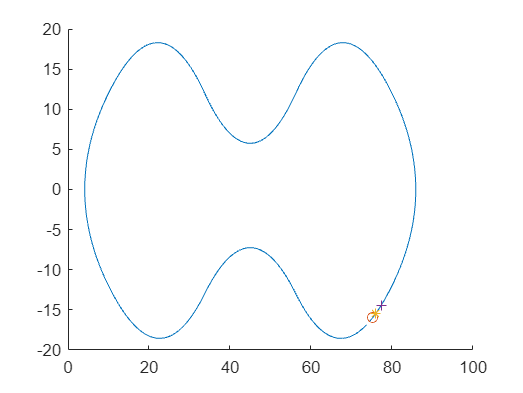

plot(set4(1,:),set4(2,:))
plot(set4(1,A),set4(2,A),'o')
plot(set4(1,B),set4(2,B),'*')
plot(set4(1,C),set4(2,C),'+')
hold off


figure
hold on
set5 = set5'

set5 =    34.7179   34.1138   33.5242   32.9245   32.3062   31.6672   31.0077   30.3266   29.6228   28.8955   28.1444   27.3697   26.5721   25.7532   24.9154   24.0616   23.1964   22.3249   21.4522   20.5835   19.7235   18.8765   18.0457   17.2331   16.4401   15.6677   14.9159   14.1846   13.4733   12.7811   12.1070   11.4508   10.8118   10.1879    9.5802    8.9903    8.4191    7.8691    7.3442    6.8459    6.3773    5.9419    5.5435    5.1861    4.8737    4.6103    4.4019    4.2501    4.1573    4.1250
   10.9721   11.6026   12.2467   12.8813   13.4979   14.0930   14.6653   15.2116   15.7283   16.2114   16.6565   17.0590   17.4140   17.7165   17.9621   18.1440   18.2605   18.3105   18.2916   18.2050   18.0551   17.8435   17.5751   17.2560   16.8906   16.4837   16.0397   15.5626   15.0563   14.5241   13.9690   13.3929   12.7978   12.1869   11.5599   10.9161   10.2557    9.5775    8.8797    8.1627    7.4260    6.6692    5.8923    5.0957    4.2804    3.4480    2.6002    1.7405    0.8724  

set5_ = set5_'

set5_ =    35.3402   35.9818   36.6440   37.3288   38.0366   38.7681   39.5238   40.3042   41.1082   41.9338   42.7782   43.6380   44.5072   45.3801   46.2501   47.1115   47.9581   48.7862   49.5931   50.3767   51.1358   51.8703   52.5812   53.2686   53.9337   54.5780   55.2028   55.8091   56.3996   56.9969   57.6128   58.2492   58.9059   59.5841   60.2848   61.0090   61.7571   62.5288   63.3236   64.1399   64.9754   65.8273   66.6913   67.5623   68.4352   69.3046   70.1660   71.0150   71.8480   72.6630
   10.3596    9.7673    9.1982    8.6565    8.1452    7.6685    7.2311    6.8397    6.4994    6.2158    5.9940    5.8431    5.7633    5.7579    5.8288    5.9706    6.1834    6.4595    6.7929    7.1780    7.6094    8.0813    8.5884    9.1268    9.6925   10.2819   10.8918   11.5201   12.1635   12.8004   13.4193   14.0172   14.5927   15.1426   15.6634   16.1512   16.6015   17.0097   17.3710   17.6804   17.9334   18.1245   18.2492   18.3076   18.2984   18.2198   18.0777   17.8746   17.6129 

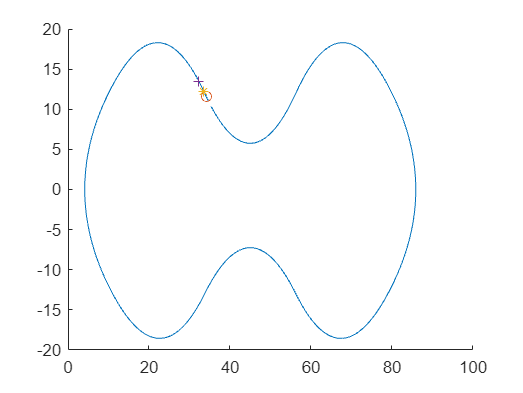

plot(set5(1,:),set5(2,:))
plot(set5(1,A),set5(2,A),'o')
plot(set5(1,B),set5(2,B),'*')
plot(set5(1,C),set5(2,C),'+')
hold off

%discretizationDistance = 0.05; % Smaller distance between points for higher resolution
%refPath = referencePathFrenet(waypoints, discretizationDistance);
%for x =[set1 set1_ set2 set2_ set3 set3_ set4 set4_ set5 set5_]
    refPath_ = referencePathFrenet(set1');
    
    %pathPoints = refPath1.path;
    % Define waypoints
    waypoints = [refPath_.SegmentParameters(:,1) refPath_.SegmentParameters(:,2)];
    
    % Define desired number of interpolated points
    %for x =[216 288 432 864 2160]
    numInterpolatedPoints = 864;  % This will give a higher resolution path
    
    % Generate cumulative arc length
    distances = sqrt(sum(diff(waypoints).^2, 2));
    arcLength = [0; cumsum(distances)];
    
    % Create interpolation functions
    xInterp = @(s) interp1(arcLength, waypoints(:, 1), s, 'linear');
    yInterp = @(s) interp1(arcLength, waypoints(:, 2), s, 'linear');
    
    % Generate interpolated points
    sInterpolated = linspace(0, arcLength(end), numInterpolatedPoints);
    xInterpolated = xInterp(sInterpolated);
    yInterpolated = yInterp(sInterpolated);
    
    % Combine interpolated points
    interpolatedWaypoints = [xInterpolated', yInterpolated'];
    
    % Create referencePathFrenet object with the interpolated waypoints
    discretizationDistance = (arcLength(end) / (numInterpolatedPoints - 1));
    refPath1 = referencePathFrenet(interpolatedWaypoints,'DiscretizationDistance', discretizationDistance);
%end
% Get the path points
%pathPoints = refPath.Waypoints;
%{
% Visualize the reference path
figure;
hold on;
grid on;
plot(waypoints(:, 1), waypoints(:, 2), 'ro', 'DisplayName', 'Original Waypoints');
plot(pathPoints(:, 1), pathPoints(:, 2), 'b*', 'DisplayName', 'Interpolated Path');
legend;
xlabel('X');
ylabel('Y');
title('High Resolution Path Interpolation');
hold off;

% Display the number of waypoints generated
disp('Number of waypoints generated:');
disp(size(pathPoints, 1));
%}

%{
refPath1 = referencePathFrenet(set1');
refPath2 = referencePathFrenet(set2');
refPath3 = referencePathFrenet(set3');
refPath4 = referencePathFrenet(set4');
refPath5 = referencePathFrenet(set5');
refPath1_ = referencePathFrenet(set1_');
refPath2_ = referencePathFrenet(set2_');
refPath3_ = referencePathFrenet(set3_');
refPath4_ = referencePathFrenet(set4_');
refPath5_ = referencePathFrenet(set5_');
%}

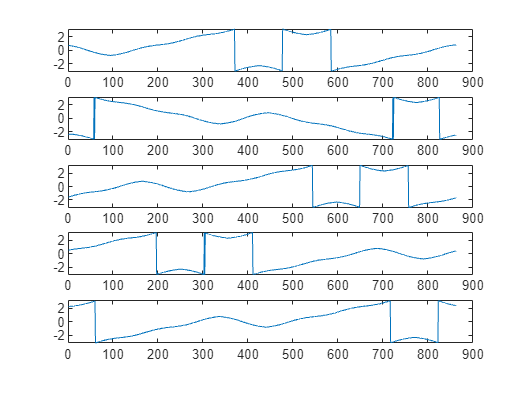

figure

subplot(5,1,1)
plot(refPath1.SegmentParameters(:,3))

subplot(5,1,2)
plot(refPath1_.SegmentParameters(:,3))

subplot(5,1,3)
plot(refPath3.SegmentParameters(:,3))

subplot(5,1,4)
plot(refPath4.SegmentParameters(:,3))

subplot(5,1,5)
plot(refPath5.SegmentParameters(:,3))

quat1 = eul2quat([refPath1.SegmentParameters(:,3),zeros(length(refPath1.SegmentParameters(:,3)),1),zeros(length(refPath1.SegmentParameters(:,3)),1)]);
ArcPath1 = [refPath1.SegmentParameters(:,1),refPath1.SegmentParameters(:,2),refPath1.SegmentParameters(:,3),quat1(:,1),quat1(:,2),quat1(:,3),quat1(:,4),refPath1.SegmentParameters(:,4),refPath1.SegmentParameters(:,5),refPath1.SegmentParameters(:,6)];

quat1_ = eul2quat([refPath1_.SegmentParameters(:,3),zeros(length(refPath1_.SegmentParameters(:,3)),1),zeros(length(refPath1_.SegmentParameters(:,3)),1)]);
ArcPath1_ = [refPath1_.SegmentParameters(:,1),refPath1_.SegmentParameters(:,2),refPath1_.SegmentParameters(:,3),quat1_(:,1),quat1_(:,2),quat1_(:,3),quat1_(:,4),refPath1_.SegmentParameters(:,4),refPath1_.SegmentParameters(:,5),refPath1_.SegmentParameters(:,6)];


quat2 = eul2quat([refPath2.SegmentParameters(:,3),zeros(length(refPath2.SegmentParameters(:,3)),1),zeros(length(refPath2.SegmentParameters(:,3)),1)]);
ArcPath2 = [refPath2.SegmentParameters(:,1),refPath2.SegmentParameters(:,2),refPath2.SegmentParameters(:,3),quat2(:,1),quat2(:,2),quat2(:,3),quat2(:,4),refPath2.SegmentParameters(:,4),refPath2.SegmentParameters(:,5),refPath2.SegmentParameters(:,6)];

quat2_ = eul2quat([refPath2_.SegmentParameters(:,3),zeros(length(refPath2_.SegmentParameters(:,3)),1),zeros(length(refPath2_.SegmentParameters(:,3)),1)]);
ArcPath2_ = [refPath2_.SegmentParameters(:,1),refPath2_.SegmentParameters(:,2),refPath2_.SegmentParameters(:,3),quat2_(:,1),quat2_(:,2),quat2_(:,3),quat2_(:,4),refPath2_.SegmentParameters(:,4),refPath2_.SegmentParameters(:,5),refPath2_.SegmentParameters(:,6)];

quat3 = eul2quat([refPath3.SegmentParameters(:,3),zeros(length(refPath3.SegmentParameters(:,3)),1),zeros(length(refPath3.SegmentParameters(:,3)),1)]);
ArcPath3 = [refPath3.SegmentParameters(:,1),refPath3.SegmentParameters(:,2),refPath3.SegmentParameters(:,3),quat3(:,1),quat3(:,2),quat3(:,3),quat3(:,4),refPath3.SegmentParameters(:,4),refPath3.SegmentParameters(:,5),refPath3.SegmentParameters(:,6)];

quat3_ = eul2quat([refPath3_.SegmentParameters(:,3),zeros(length(refPath3_.SegmentParameters(:,3)),1),zeros(length(refPath3_.SegmentParameters(:,3)),1)]);
ArcPath3_ = [refPath3_.SegmentParameters(:,1),refPath3_.SegmentParameters(:,2),refPath3_.SegmentParameters(:,3),quat3_(:,1),quat3_(:,2),quat3_(:,3),quat3_(:,4),refPath3_.SegmentParameters(:,4),refPath3_.SegmentParameters(:,5),refPath3_.SegmentParameters(:,6)];

quat4 = eul2quat([refPath4.SegmentParameters(:,3),zeros(length(refPath4.SegmentParameters(:,3)),1),zeros(length(refPath4.SegmentParameters(:,3)),1)]);
ArcPath4 = [refPath4.SegmentParameters(:,1),refPath4.SegmentParameters(:,2),refPath4.SegmentParameters(:,3),quat4(:,1),quat4(:,2),quat4(:,3),quat4(:,4),refPath4.SegmentParameters(:,4),refPath4.SegmentParameters(:,5),refPath4.SegmentParameters(:,6)];

quat4_ = eul2quat([refPath4_.SegmentParameters(:,3),zeros(length(refPath4_.SegmentParameters(:,3)),1),zeros(length(refPath4_.SegmentParameters(:,3)),1)]);
ArcPath4_ = [refPath4_.SegmentParameters(:,1),refPath4_.SegmentParameters(:,2),refPath4_.SegmentParameters(:,3),quat4_(:,1),quat4_(:,2),quat4_(:,3),quat4_(:,4),refPath4_.SegmentParameters(:,4),refPath4_.SegmentParameters(:,5),refPath4_.SegmentParameters(:,6)];

quat5 = eul2quat([refPath5.SegmentParameters(:,3),zeros(length(refPath5.SegmentParameters(:,3)),1),zeros(length(refPath5.SegmentParameters(:,3)),1)]);
ArcPath5 = [refPath5.SegmentParameters(:,1),refPath5.SegmentParameters(:,2),refPath5.SegmentParameters(:,3),quat5(:,1),quat5(:,2),quat5(:,3),quat5(:,4),refPath5.SegmentParameters(:,4),refPath5.SegmentParameters(:,5),refPath5.SegmentParameters(:,6)];

quat5_ = eul2quat([refPath5_.SegmentParameters(:,3),zeros(length(refPath5_.SegmentParameters(:,3)),1),zeros(length(refPath5_.SegmentParameters(:,3)),1)]);
ArcPath5_ = [refPath5_.SegmentParameters(:,1),refPath5_.SegmentParameters(:,2),refPath5_.SegmentParameters(:,3),quat5_(:,1),quat5_(:,2),quat5_(:,3),quat5_(:,4),refPath5_.SegmentParameters(:,4),refPath5_.SegmentParameters(:,5),refPath5_.SegmentParameters(:,6)];

save(strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPathFlipWs.mat'))

writematrix(ArcPath1,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath1.csv'))
writematrix(ArcPath2,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath2.csv'))
writematrix(ArcPath3,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath3.csv'))
writematrix(ArcPath4,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath4.csv'))
writematrix(ArcPath5,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath5.csv'))

writematrix(ArcPath1_,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath1_.csv'))
writematrix(ArcPath2_,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath2_.csv'))
writematrix(ArcPath3_,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath3_.csv'))
writematrix(ArcPath4_,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath4_.csv'))
writematrix(ArcPath5_,strcat('D:\Work\Code\FrenetArcLength\UpdatedPath\MixPolicy\',folder,specifier,'ArcPath5_.csv'))